# Machine Learning with MATLAB

Digital Twin & Automation

# Decision Tree

## Data Acquisition

### Dataset 1:  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

clear

%% Train
load("../5weeks_machine_learning_2/CWRU_features/example_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));
Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);

%% Test
load("../5weeks_machine_learning_2/CWRU_features/example_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);





#### Plot Test Data

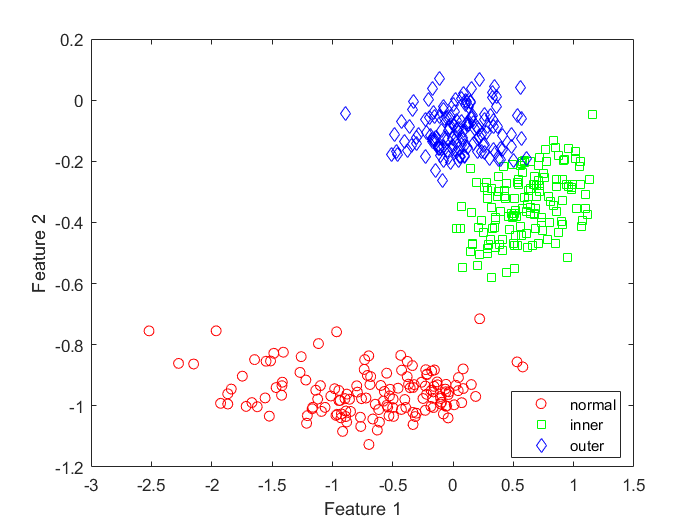

f = figure;
gscatter(X(:, 1), X(:, 2), Y,'rgb','osd');
xlabel('Feature 1')
ylabel('Feature 2')

## Prepare Cross-Validation Data

 `cvpartition` to generate 10 disjoint stratified subsets.

rng(0)
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

# **Decision Tree**

### Fit decision Tree

t = fitctree(X, Y,'PredictorNames',{'SV' 'IF' });

### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

tResubErr = resubLoss(t)

tResubErr = 0.0023

**Confusion matrix** on the training set

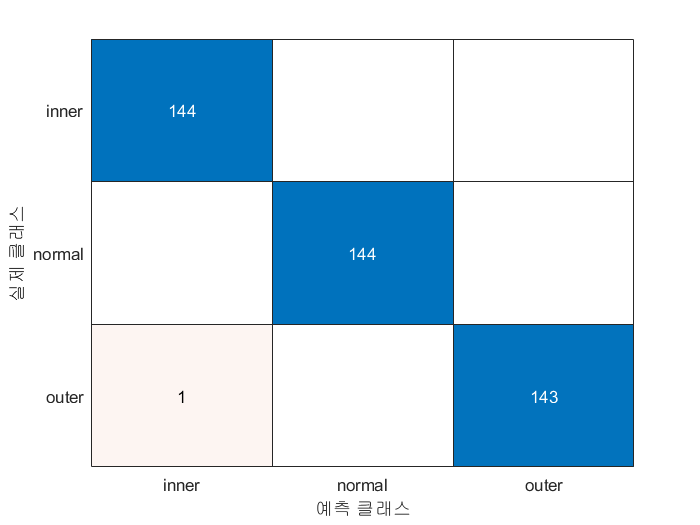

tClass = resubPredict(t);
figure
tResubCM = confusionchart(Y,tClass);

**Misclassification Plot**

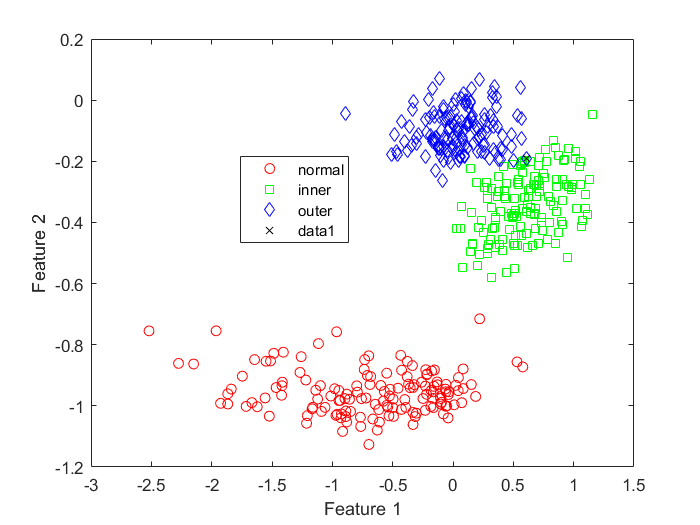

figure(f)
bad = ~strcmp(tClass,Y);
hold on;
plot(X(bad,1), X(bad,2), 'kx');
hold off;

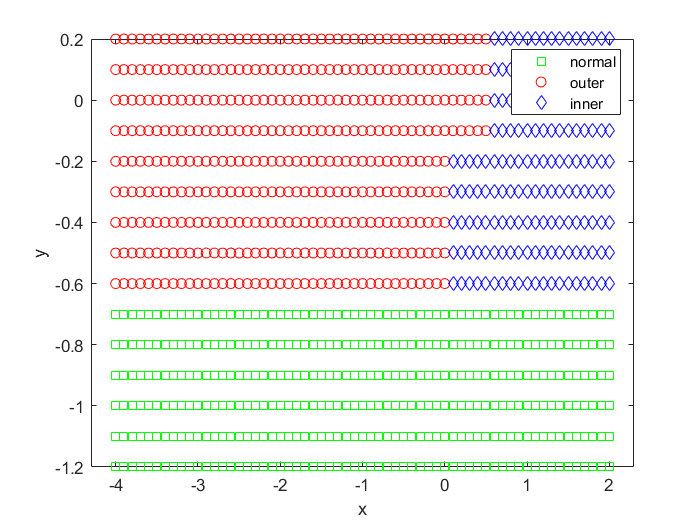



% Visualize Separation regions 
[x,y] = meshgrid(-4:.1:2,-1.2:.1:0.2);
x = x(:);
y = y(:);
[grpname,node] = predict(t,[x y]);
gscatter(x,y,grpname,'grb','sod')

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

cvt = crossval(t,'CVPartition',cv);
tCVErr = kfoldLoss(cvt)

tCVErr = 0.0069

**visualize the decision tree **

view(t,'Mode','graph');

**Prune tree nodes to enhance result**

- First compute the resubstitution error for various subsets of the original tree. 

- Then compute the cross-validation error for these sub-trees. 

resubcost = resubLoss(t,'Subtrees','all')

resubcost =     0.0023
    0.0093
    0.0347
    0.3333
    0.6667


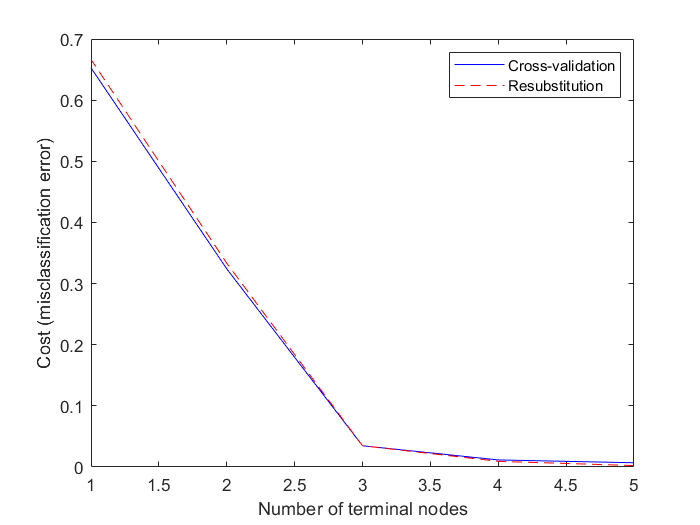

[cost,secost,ntermnodes,bestlevel] = cvloss(t,'Subtrees','all');
%[cross-validation classification error, 
% standard error, Number of leaf nodes,Best pruning level]
plot(ntermnodes,cost,'b-', ntermnodes,resubcost,'r--')
xlabel('Number of terminal nodes');
ylabel('Cost (misclassification error)')
legend('Cross-validation','Resubstitution')

% Prune Tree Levels
pt = prune(t,'Level',bestlevel);
cost(bestlevel+1)

ans = 0.0069

view(pt,'Mode','graph')


# Exercise

## Exercise 1: 

Now, Select any 3 features and repeat the process. 

**Features**

clear

 % Example
load("../5weeks_machine_learning_2/CWRU_features/example_train.mat");
X(:, 1) = table2array(glob_all_train(:, "kv"));       % Kurtosis value of time data
X(:, 2) = table2array(glob_all_train(:, "mf"));       % Marginal-Factor
X(:, 3) = table2array(glob_all_train(:, "cf"));       % Marginal-Factor

Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);


%% Test
load("../5weeks_machine_learning_2/CWRU_features/example_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, "kv"));
Xtest(:, 2) = table2array(glob_all_test(:, "mf"));
Xtest(:, 3) = table2array(glob_all_test(:, "cf"));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);

Plot the test and train results in 3D graph.

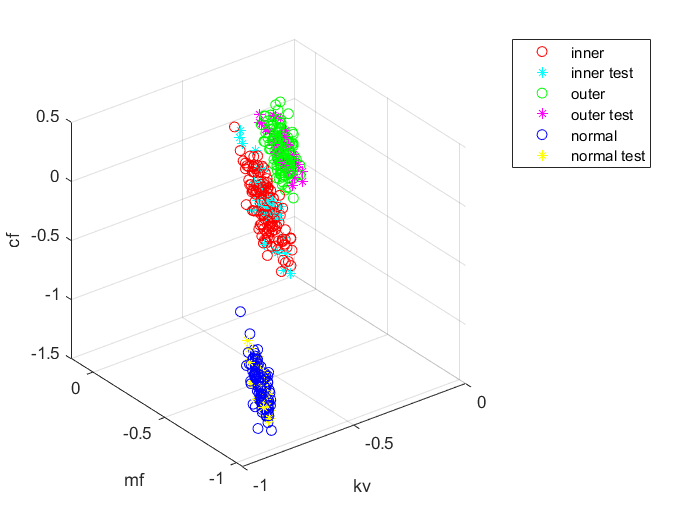

% Your code goes here
% Your code goes here
Y_cate = categorical(Y);
idx_inner = Y_cate == 'inner';
idx_outer = Y_cate == 'outer';
idx_normal = Y_cate == 'normal';
Y_cate_test = categorical(Ytest);
idx_inner_test = Y_cate_test == 'inner';
idx_outer_test = Y_cate_test == 'outer';
idx_normal_test = Y_cate_test == 'normal';





figure
plot3(X(idx_inner,1),X(idx_inner,2),X(idx_inner,3),'ro')
hold on
plot3(Xtest(idx_inner_test,1),Xtest(idx_inner_test,2),Xtest(idx_inner_test,3),'c*') 
plot3(X(idx_outer,1),X(idx_outer,2),X(idx_outer,3),'go')
plot3(Xtest(idx_outer_test,1),Xtest(idx_outer_test,2),Xtest(idx_outer_test,3),'m*')
plot3(X(idx_normal,1),X(idx_normal,2),X(idx_normal,3),'bo') 
plot3(Xtest(idx_normal_test,1),Xtest(idx_normal_test,2),Xtest(idx_normal_test,3),'y*')
grid on
xlabel('kv')
ylabel('mf')
zlabel('cf')
legend('inner','inner test','outer','outer test','normal','normal test')
hold off

## Prepare Cross-Validation Data

 `cvpartition` to generate 10 disjoint stratified subsets.

rng(0)
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

### Fit decision Tree

Mdl = fitctree(X, Y,'PredictorNames',{'KV' 'MF' 'CF'});

**Resubstitution error**:  misclassification error  on the training set.

MdlResubErr = resubLoss(Mdl)

MdlResubErr = 0

**Confusion matrix** on the training set

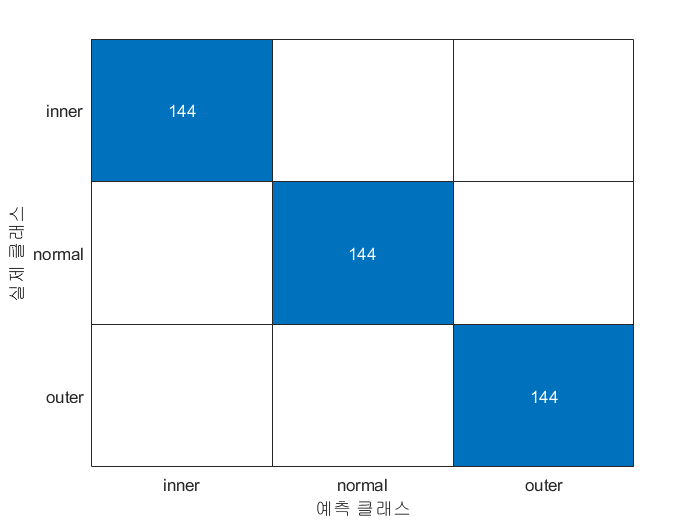

MdlClass = resubPredict(Mdl);
figure
MdlResubCM = confusionchart(Y,MdlClass);

## Exercise 2 

Compare performance with other classification 

## Exercise 3 

 How can you apply random forest in Matlab?